# Centrifugal Governator

Cominciamo con l'integrare numericamente il sistema nel caso in cui la velocità di rotazione sia costante e lineare con il tempo

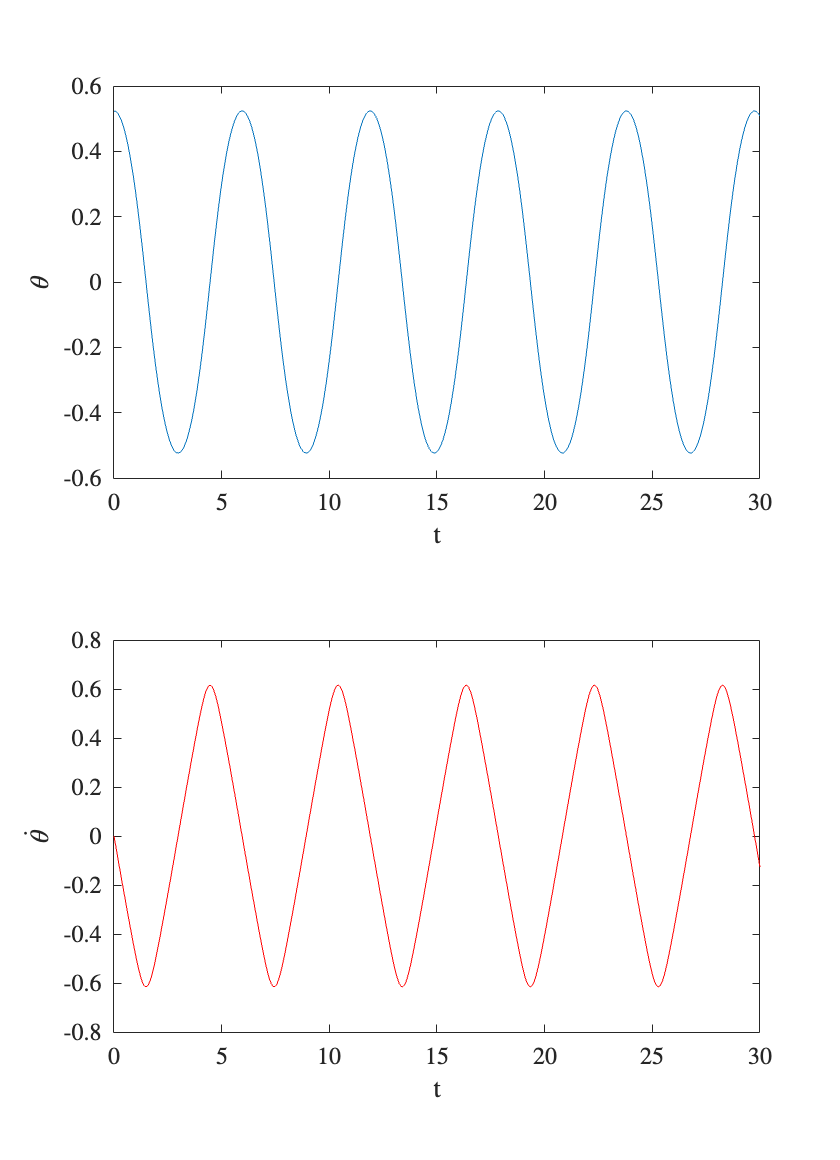

clear;
clearvars;
m1 = 4;
m2 = 8;%kg
w = 3; %rad/s
a = 3; %m
g = 9.81;
dt = (0:0.05:30);
%theta theta_p
x0 =[pi/6,0];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)sistema_w_cost(m1, m2, a, w, x, t),dt,x0,opts);
prima_ris = figure;
tilt1 = tiledlayout(2,1);
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
nexttile;
plot(t,x(:,1));
xlabel("t", 'Interpreter','latex');
ylabel("$\theta$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);


nexttile;
plot(t,x(:,2),'r');
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta}$",'Interpreter','latex');
%exportgraphics(prima_ris,'prima_ris.eps','Resolution','300');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

Studio parametrico sul sistema semplificato (studiamo le masse)

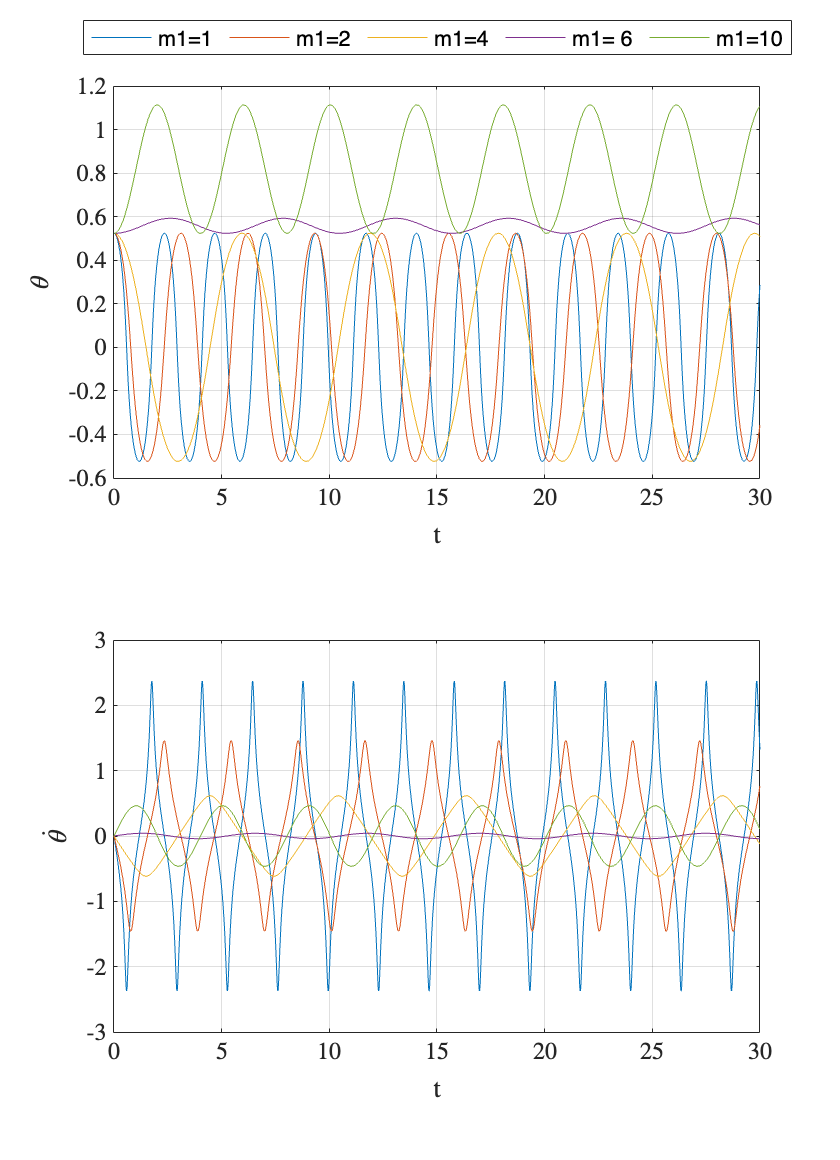

%variamo m1
x0 = [pi/6,0];
m2 = 8;
a = 3;
w = 3;
studio_parametrico_m1 = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
tilt2 = tiledlayout(2,1);
nexttile;
m1_val = [1, 2, 4, 6, 10];
for i = 1:length(m1_val)
    [t,x] = ode45(@(t,x)sistema_w_cost(m1_val(i), m2, a, w, x, t),dt,x0,opts);
    plot(t,x(:,1));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\theta$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
    end  
end
nexttile;
for i = 1:length(m1_val)
    [t,x] = ode45(@(t,x)sistema_w_cost(m1_val(i), m2, a, w, x, t),dt,x0,opts);
    plot(t,x(:,2));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\dot{\theta}$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
         grid on;
    end
end
lh =legend('m1=1','m1=2','m1=4','m1= 6','m1=10','Location','NorthOutside','Orientation','Horizontal');
lh.Layout.Tile = 'North';

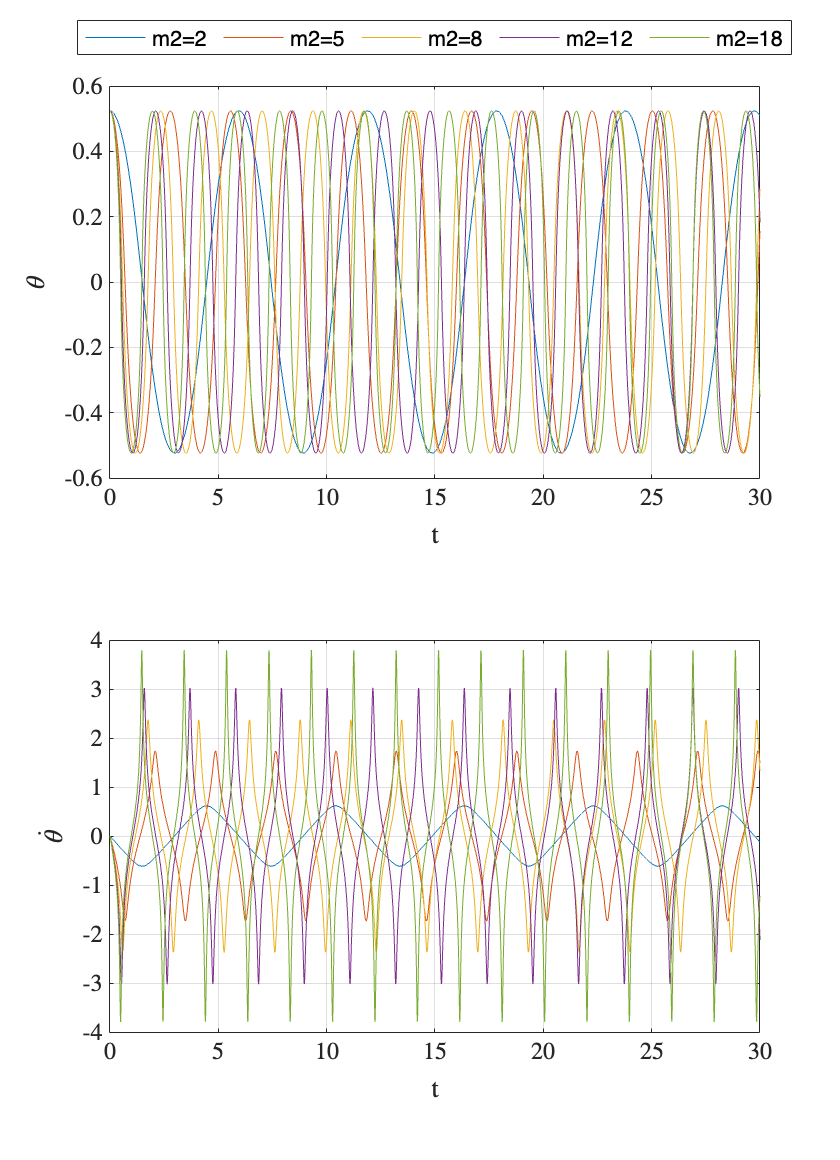

%exportgraphics(studio_parametrico_m1,'studio_parametrico_m1.eps','Resolution','300');

%studio parametrico su m2
studio_parametrico_m2 = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
tilt3 = tiledlayout(2,1);
nexttile;
m2_val = [2, 5, 8, 12, 18];
for i = 1:length(m2_val)
    [t,x] = ode45(@(t,x)sistema_w_cost(m1, m2_val(i), a, w, x, t),dt,x0,opts);
    plot(t,x(:,1));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\theta$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
    end  
end
nexttile;
for i = 1:length(m2_val)
    [t,x] = ode45(@(t,x)sistema_w_cost(m1, m2_val(i), a, w, x, t),dt,x0,opts);
    plot(t,x(:,2));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\dot{\theta}$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
         grid on;
    end
end
leg = legend('m2=2', 'm2=5', 'm2=8', 'm2=12', 'm2=18','Orientation', 'Horizontal');
leg.Layout.Tile = 'north';

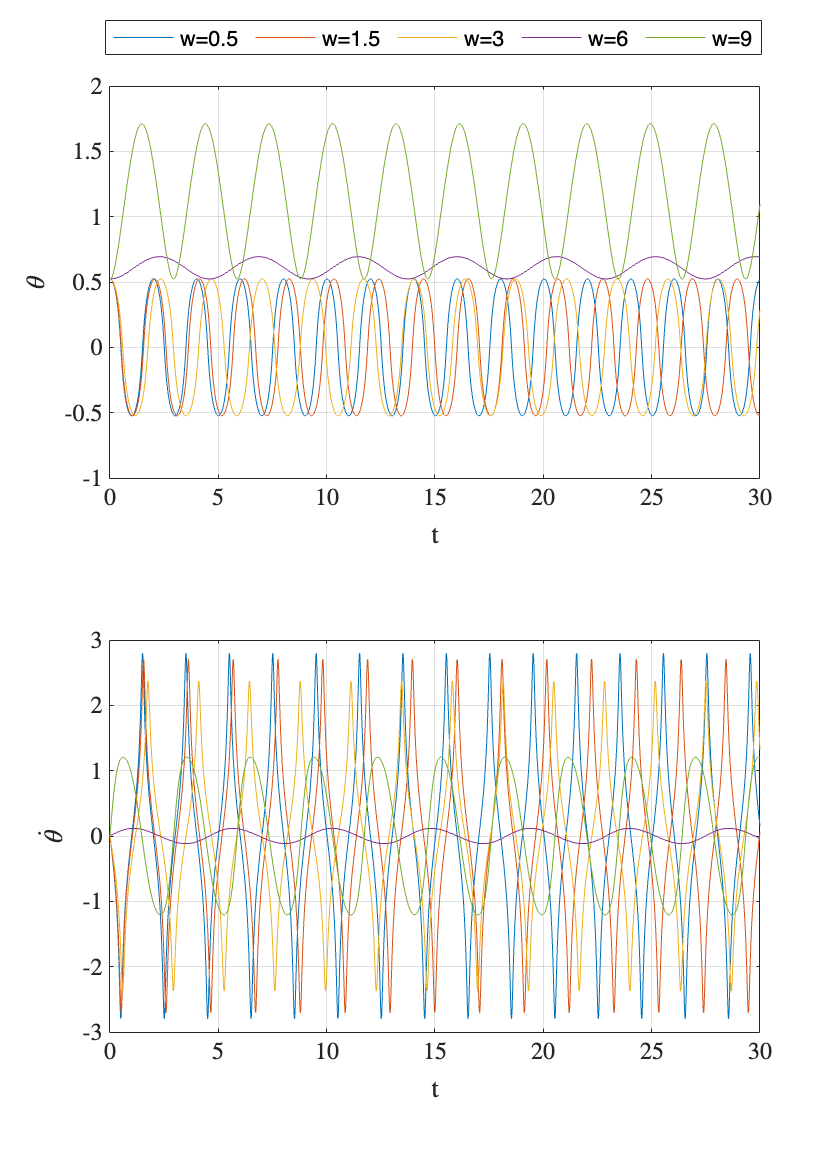

%exportgraphics(studio_parametrico_m2,'studio_parametrico_m2.eps','Resolution','300');

%studio parametrico su w
studio_parametrico_w = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
tilt4 = tiledlayout(2,1);
nexttile;
w_val = [0.5, 1.5, 3, 6, 9];
for i = 1:length(w_val)
    [t,x] = ode45(@(t,x)sistema_w_cost(m1, m2, a, w_val(i), x, t),dt,x0,opts);
    plot(t,x(:,1));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\theta$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
    end  
end
nexttile;
for i = 1:length(m2_val)
    [t,x] = ode45(@(t,x)sistema_w_cost(m1, m2, a, w_val(i), x, t),dt,x0,opts);
    plot(t,x(:,2));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\dot{\theta}$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
    end
end
leg = legend('w=0.5', 'w=1.5', 'w=3','w=6', 'w=9','Orientation', 'Horizontal');
leg.Layout.Tile = 'north';

%exportgraphics(studio_parametrico_w,'studio_parametrico_w.eps','Resolution','300');

Studio sistema non semplificato

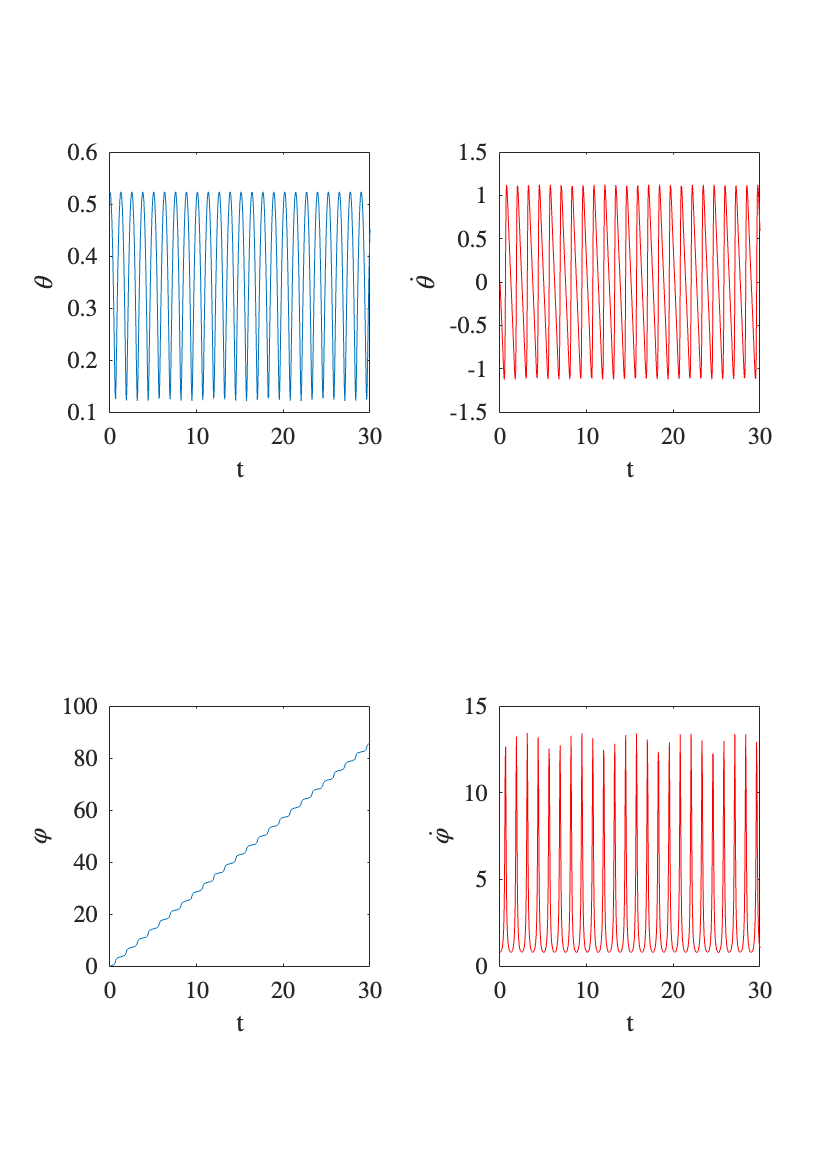

x0_w_var =[pi/6, 0, 0, pi/4];
[t,x] = ode45(@(t,x)sistema_w_variabile(m1, m2, a, x, t),dt,x0_w_var,opts);
w_var_prima_ris = figure;
tilt5 = tiledlayout(2,2);
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
nexttile;
plot(t,x(:,1));
xlabel("t", 'Interpreter','latex');
ylabel("$\theta$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
axis square;

nexttile;
plot(t,x(:,3),'r');
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
axis square;

nexttile;
plot(t,x(:,2));
xlabel("t", 'Interpreter','latex');
ylabel("$\varphi$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
axis square;

nexttile;
plot(t,x(:,4),'r');
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\varphi}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
axis square;

%exportgraphics(w_var_prima_ris,'w_var_prima_ris.eps','Resolution','300');

Studio parametrico sul sistema variabile

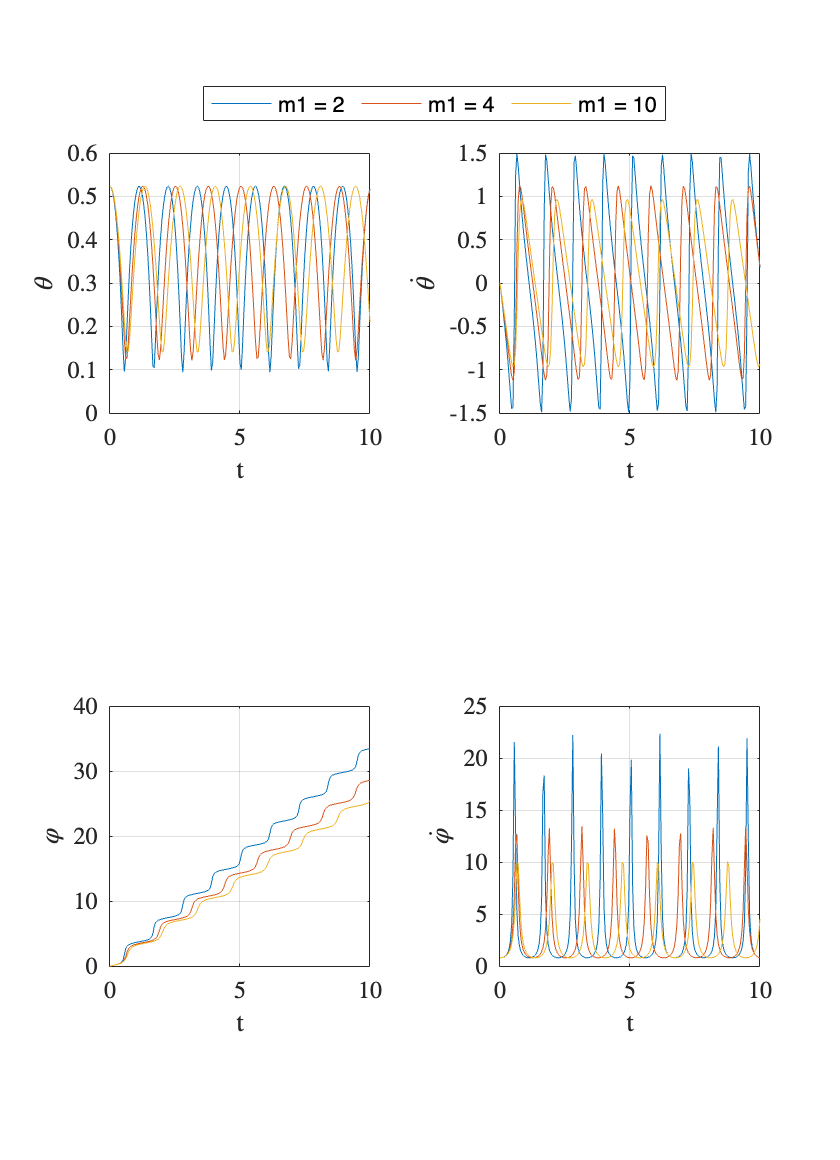

%variazione di m1
studio_parametrico_m1_w = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
tilt6 = tiledlayout(2,2);
nexttile;
m1_val = [2, 4, 6];
dt = (0:0.05:10);
for i = 1:length(m1_val)
    [t,x] = ode45(@(t,x)sistema_w_variabile(m1_val(i), m2, a, x, t),dt,x0_w_var,opts);
    plot(t,x(:,1));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\theta$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
        axis square;
    end  
end
nexttile;
for i = 1:length(m1_val)
    [t,x] = ode45(@(t,x)sistema_w_variabile(m1_val(i), m2, a, x, t),dt,x0_w_var,opts);
    plot(t,x(:,3));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\dot{\theta}$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
         axis square;
    end
end
nexttile;
for i = 1:length(m1_val)
    [t,x] = ode45(@(t,x)sistema_w_variabile(m1_val(i), m2, a, x, t),dt,x0_w_var,opts);
    plot(t,x(:,2));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\varphi$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
         axis square;
    end  
end
nexttile;
for i = 1:length(m1_val)
    [t,x] = ode45(@(t,x)sistema_w_variabile(m1_val(i), m2, a, x, t),dt,x0_w_var,opts);
    plot(t,x(:,4));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\dot{\varphi}$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
         axis square;
    end
end



leg = legend('m1 = 2','m1 = 4','m1 = 10','Orientation', 'Horizontal');


leg.Layout.Tile = 'north';

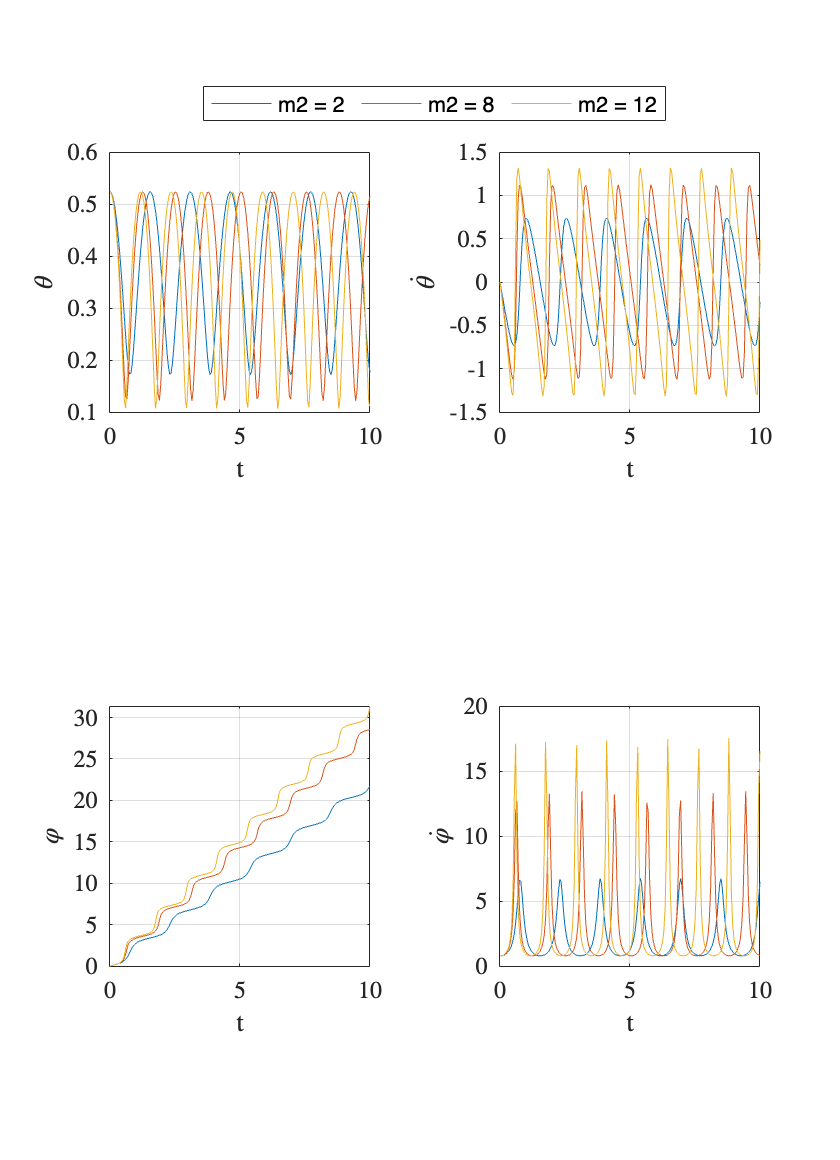

%exportgraphics(studio_parametrico_m1_w,'studio_parametrico_m1_w.eps','Resolution','300');
%studio parametrico m2
studio_parametrico_m2_w = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
tilt3 = tiledlayout(2,2);
nexttile;
m2_val = [2, 8, 12,];
for i = 1:length(m2_val)
    [t,x] = ode45(@(t,x)sistema_w_variabile(m1, m2_val(i), a, x, t),dt,x0_w_var,opts);
    plot(t,x(:,1));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\theta$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
        axis square;
    end  
end
nexttile;
for i = 1:length(m2_val)
    [t,x] = ode45(@(t,x)sistema_w_variabile(m1, m2_val(i), a, x, t),dt,x0_w_var,opts);
    plot(t,x(:,3));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\dot{\theta}$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
        axis square;        
    end
end
nexttile;
for i = 1:length(m2_val)
    [t,x] = ode45(@(t,x)sistema_w_variabile(m1, m2_val(i), a, x, t),dt,x0_w_var,opts);
    plot(t,x(:,2));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\varphi$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
        axis square;        
    end  
end
nexttile;
for i = 1:length(m2_val)
    [t,x] = ode45(@(t,x)sistema_w_variabile(m1, m2_val(i), a, x, t),dt,x0_w_var,opts);
    plot(t,x(:,4));
    if (i==1)
        hold on;
        xlabel("t", 'Interpreter','latex');
        ylabel("$\dot{\varphi}$",'Interpreter','latex');
        set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
        grid on;
        axis square;        
    end
end

leg = legend('m2 = 2', 'm2 = 8', 'm2 = 12','Orientation', 'Horizontal');

leg.Layout.Tile = 'north';

%exportgraphics(studio_parametrico_m2_w,'studio_parametrico_m2_w.eps','Resolution','300');

Coordinate cartesiane:

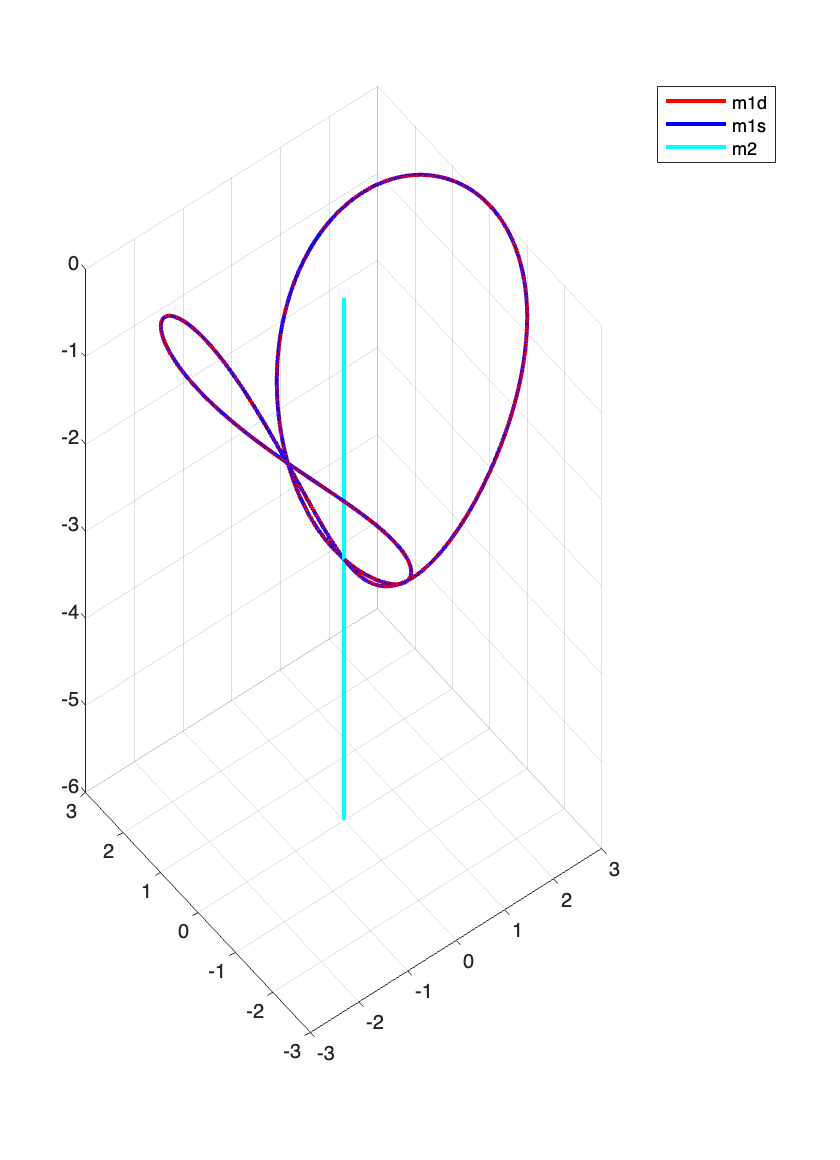

%cominciamo dal sistema con w fissata:
%l = 0.5 m1 =1 m2 = 2 w = 5 th = pi/2
dt = (0:0.005:100); 
a = 3;
m1 = 10;
m2 = 8;
w = 3;
x0 =[pi/2,0];
[t,x] = ode45(@(t,x)sistema_w_cost(m1, m2, a, w, x, t),dt,x0,opts);
x_m1d = a*sin(x(:,1)).*cos(x(:,2));
y_m1d = a*sin(x(:,1)).*sin(x(:,2));
z_m1d = -a*cos(x(:,1));

x_m1s = x_m1d;
y_m1s = -y_m1d;
z_m1s = z_m1d;

x_m2 = zeros(size(x(:,1)));
y_m2 = zeros(size(x(:,1)));
z_m2 = -2*a*cos(x(:,1));

traiettorie_cartesiane_w_cost = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

plot3(x_m1d,y_m1d,z_m1d, 'r','LineWidth', 2);
hold on;
plot3(x_m1s,y_m1s,z_m1s, 'b','LineWidth', 2);
plot3(x_m2,y_m2,z_m2, 'c','LineWidth', 2);
grid on;
legend('m1d','m1s','m2');

%exportgraphics(traiettorie_cartesiane_w_cost,'traiettorie_cartesiane_w_cost_2.eps','Resolution','300');

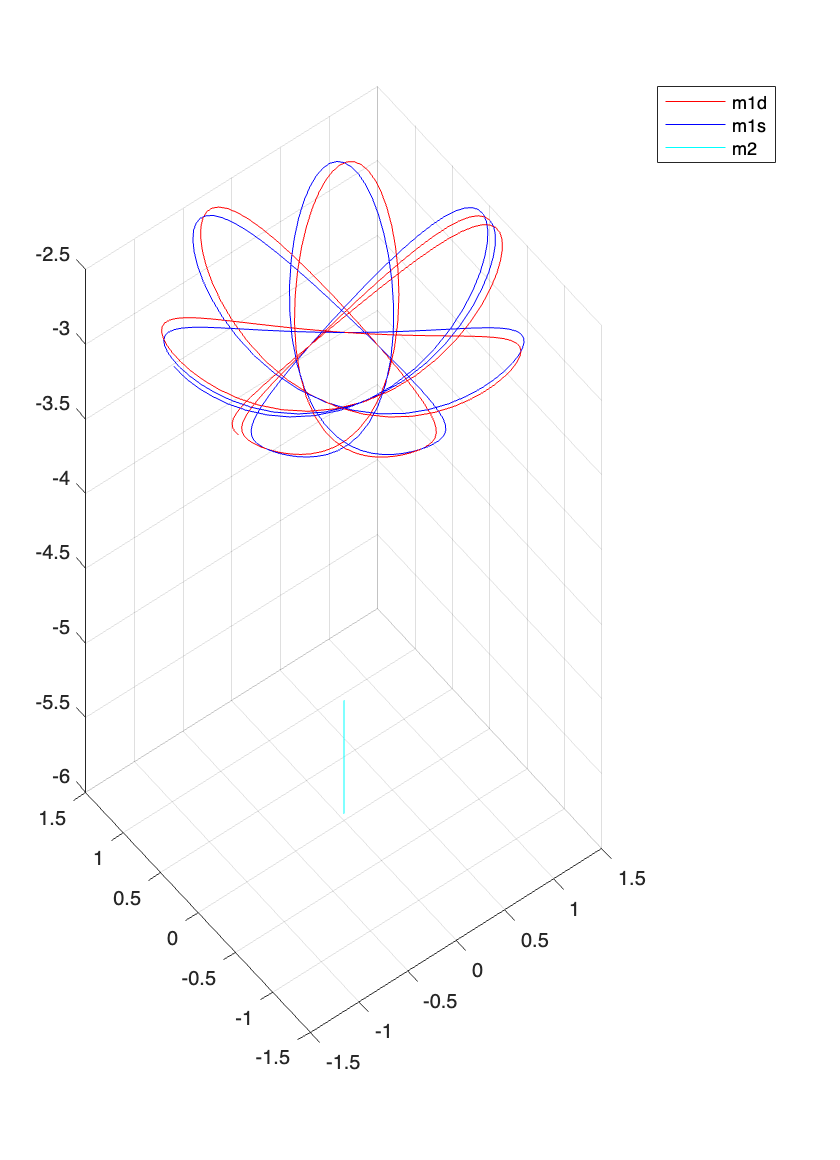

%passiamo al sistema con w variabile:
x0_w_var =[pi/6, 0, 0, pi/4];
m1 = 4;
m2 = 8;%kg
a = 3; %m;
%dt = (0:0.05:140);
[t,x] = ode45(@(t,x)sistema_w_variabile(m1, m2, a, x, t),dt,x0_w_var,opts);
x_m1d = a*sin(x(:,1)).*cos(x(:,2));
y_m1d = a*sin(x(:,1)).*sin(x(:,2));
z_m1d = -a*cos(x(:,1));

x_m1s = x_m1d;
y_m1s = -y_m1d;
z_m1s = z_m1d;

x_m2 = zeros(size(x(:,1)));
y_m2 = zeros(size(x(:,1)));
z_m2 = -2*a*cos(x(:,1));
traiettorie_cartesiane_w_var = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

plot3(x_m1d,y_m1d,z_m1d, 'r');
hold on;
plot3(x_m1s,y_m1s,z_m1s, 'b');
plot3(x_m2,y_m2,z_m2, 'c');
grid on;
legend('m1d','m1s','m2');

%exportgraphics(traiettorie_cartesiane_w_var,'traiettorie_cartesiane_w_var_2.eps','Resolution','300');

analisi del'andamento di theta(t), come condizioni iniziali imponiamo lo stesso theta0, e lo stesso w0:

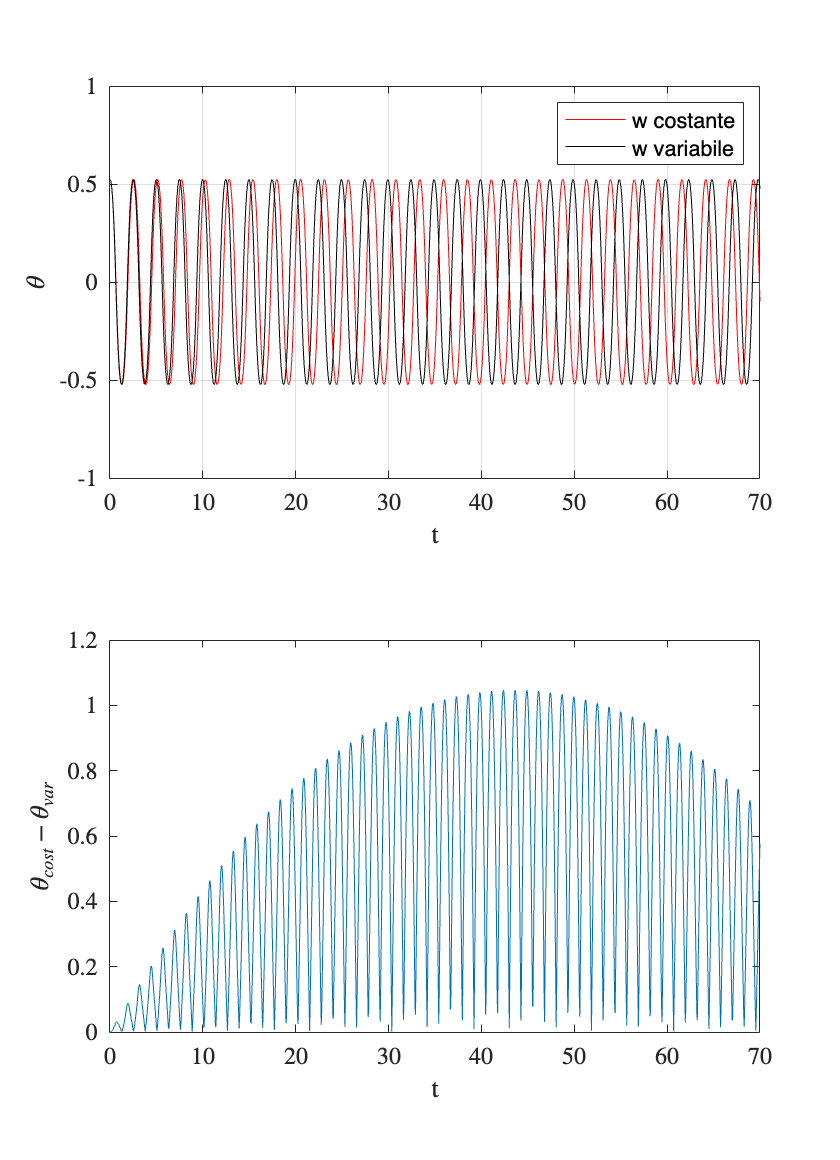

dt = (0:0.05:70);
x0 =[pi/6,0];
w = pi/4;
x0_w_var =[pi/6, 0,0,0];
[t,x_cost] = ode45(@(t,x)sistema_w_cost(m1, m2, a, w, x, t),dt,x0,opts);
[t,x_var] = ode45(@(t,x)sistema_w_variabile(m1, m2, a, x, t),dt,x0_w_var,opts);
confronto_theta = figure;
tilt7 = tiledlayout(2,1);
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
nexttile;
plot(t,x_cost(:,1),'r');
hold on;
plot(t,x_var(:,1),'k');
ylim([-1 1]);
legend('w costante', 'w variabile');
ylabel("$\theta$",'Interpreter','latex');
xlabel("t",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
grid on;
nexttile;
plot(t,abs(x_cost(:,1)-x_var(:,1)));
hold on;
%plot(t,1.0472*ones(size(t)),'r');
xlabel("t",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

ylabel("$\theta_{cost} - \theta_{var}$",'Interpreter','latex');

%exportgraphics(confronto_theta,'confronto_theta.eps','Resolution','300');